Calculation of Reflection Coefficient

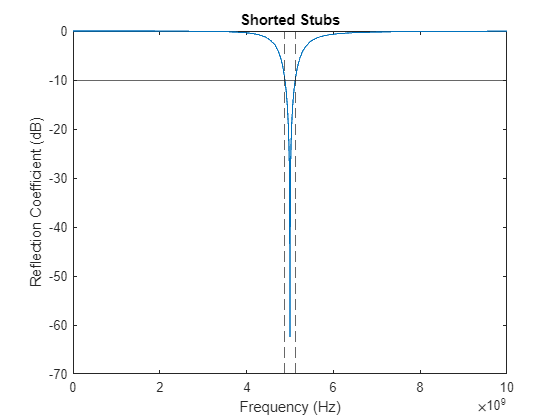

clear;
Z0=50;
ZL=10-70j;
f=0:1e5:10e9;
b=2*pi.*f/(5e9);

% TL and Stub Lengths
d=1/8;

l1_s=0.2285;
l2_s=0.0461;

l1_o=0.101;
l2_o=0.2206;

%  Short
Zstub1_s=1i.*Z0.*tan(b.*l1_s);
Zstub2_s=1i.*Z0.*tan(b.*l2_s);

Zin1=ZL.*Zstub1_s./(ZL+Zstub1_s);
Zin2=Z0*(Zin1+1i.*Z0.*tan(b.*d))./(Z0+1i*Zin1.*tan(b.*d));
Zin_s=Zin2.*Zstub2_s./(Zin2+Zstub2_s);

gamma_s=(Zin_s-Z0)./(Zin_s+Z0);
% SWR_s=(1+abs(gamma_s))./(1-abs(gamma_s));

plot(f,db(abs(gamma_s)))
title("Shorted Stubs")
ylabel("Reflection Coefficient (dB)")
xlabel("Frequency (Hz)")
yline(-10)
xline(4.883e9,'--')
xline(5.117e9,'--')

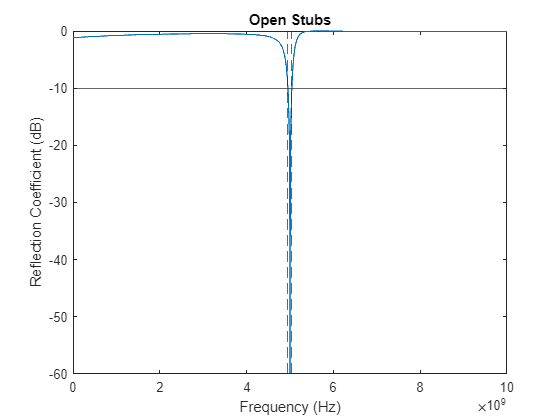

% xlim([4.5e9 5.5e9])

%  Open
Zstub1_o=-1i*Z0.*cot(b.*l1_o);
Zstub2_o=-1i*Z0.*cot(b.*l2_o);

Zin1=ZL.*Zstub1_o./(ZL+Zstub1_o);
Zin2=Z0*(Zin1+1i*Z0.*tan(b.*d))./(Z0+1i*Zin1.*tan(b.*d));
Zin=Zin2.*Zstub2_o./(Zin2+Zstub2_o);

gamma_o=(Zin-Z0)./(Zin+Z0);
% SWR_o=(1+abs(gamma_o))./(1-abs(gamma_o));

plot(f,db(abs(gamma_o)))
title("Open Stubs")
ylabel("Reflection Coefficient (dB)")
xlabel("Frequency (Hz)")
yline(-10)
xline(4.9525e9,'--')
xline(5.0425e9,'--')

% xlim([4.5e9 5.5e9])